# Análisis de Tráfico Telefónico Rural en el Perú

Este análisis de tráfico telefónico rural toma como base los datos oficiales publicados e

n la página web de indicadores estadisticos del OSIPTEL.

- [https://www.osiptel.gob.pe/documentos/8-indicadores-de-servicios-de-comunicaciones-rurales](https://www.osiptel.gob.pe/documentos/8-indicadores-de-servicios-de-comunicaciones-rurales)

### Limpiando el espacio de trabajo

clear all

## A. Descarga de datos de tráfico telefónico rural

Esta información es de acceso público y está disponible para ser descargar de la página web de indicadores estadisticos del OSIPTEL.

% Fijamos url de origen para la descargar datos de trafico
url = ['https://www.osiptel.gob.pe/repositorioaps/data/1/1/1/par/'...
    '84-trafico-anual-saliente-por-departamento-y-empr/'...
    '8.4_Trafico_anual_saliente_por_departamento.xlsx'];
% Fijamos ruta de destino local para guardar datos de trafico
filename = ['C:\Users\huber\Documents\git\telecom\rural\data\'...
    '8.4_Trafico_anual_saliente_por_departamento.xlsx'];
outfilename = websave(filename,url)

outfilename = 'C:\Users\huber\Documents\git\telecom\rural\data\8.4_Trafico_anual_saliente_por_departamento.xlsx'

## B. Trafico anual saliente en minutos (T)

Esta información, la recuperamos del archivo descargado en el paso anterior(A) el cual tiene datos de trafico saliente en minutos en un periodo de 10 años (empezando el 2006).

% Configuramos la opcion lectura de hasta 13 variables (una variable por columna)
opts = spreadsheetImportOptions("NumVariables", 13);

% Configuramos el nombre de la pagina y el rango de datos (para recuperar los datos)
opts.Sheet = "Trafico Saliente";
opts.DataRange = "A3:M32";

% Importamos los datos de trafico rural en una variable temporal
tmp = readtable(filename, opts, "UseExcel", false);
% Quitamos la columna 2, que esta vacia en la variable temporal
tmp = removevars(tmp, 2);

% Guardamos información solo de trafico, quitamos informacion adicional
trafico = tmp(3:27,1:12);

% Guardamos información adicional de trafico
info{1} = string(table2cell(tmp(1,1)));
info{2} = string(table2cell(tmp(29,1)));
info{3} = string(table2cell(tmp(30,1)));

% Copiamos la fila 2, de la tabla temporal hacia  las cabeceras de la tabla trafico
trafico.Properties.VariableNames=table2cell(tmp(2,:));

% Invertimos la tabla trafico, en base a departamentos
T = rows2vars(trafico,"VariableNamesSource","Departamento");

% Cambiamos el valor de la primera cabecera hacia "Año"
T.Properties.VariableNames(1)="Año";

% Cambiamos el tipo de string a double para los valores de trafico
for var=T.Properties.VariableNames(2:26)
    var=string(var);
    T.(var)=str2double(T.(var));
end

disp(T)

      Año        AMAZONAS       ANCASH       APURIMAC      AREQUIPA      AYACUCHO     CAJAMARCA       CUSCO       HUANCAVELICA     HUANUCO         ICA          JUNIN       LALIBERTAD    LAMBAYEQUE       LIMA         LORETO      MADREDEDIOS     MOQUEGUA       PASCO         PIURA          PUNO       SANMARTIN       TACNA         TUMBES       UCAYALI      TotalPeru 
    ________    __________    __________    __________    __________    __________    

## C. Volumen de tráfico telefónico rural total en minutos

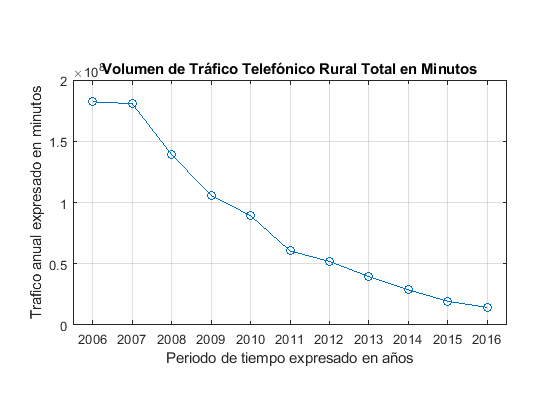

% Cambiamos la columna Año al tipo categoria
T.("Año") = categorical(T.("Año"));

% Graficamos el tráfico total por año
figure
plot(T.("Año"),T.TotalPeru,'-o')
grid on
pbaspect([16 9 1])
title('Volumen de Tráfico Telefónico Rural Total en Minutos')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico anual expresado en minutos')

% Mostramos la descripcion de los datos
fprintf('%s\n%s\n%s',info{:})

Cuadro 8.4 Tráfico anual Saliente de teléfonos públicos rurales por departamento *
(*)  Información anual del tráfico expresado en minutos de los Teléfonos Públicos  Rurales de Telefónica del Perú S.A.A, Gilat to Home S.A., Rural Telecom S.A.C. y Winner Systems S.A.C.
No se consideraron los tráficos generados por los teléfonos públicos del proyecto Banda Ancha para localidades Aisladas-BAS de Telefónica del Perú S.A.A.

## **D. Función de distribución de probabilidad para la duración promedio del tiempo de servicio**

El numero prome dio de arribo lamda y mu el intervalo de tiempo promedio entre dos arribos de llamadas. Es decir, mu=10 para un intervalo promedio de llamadas de 6 minutos.

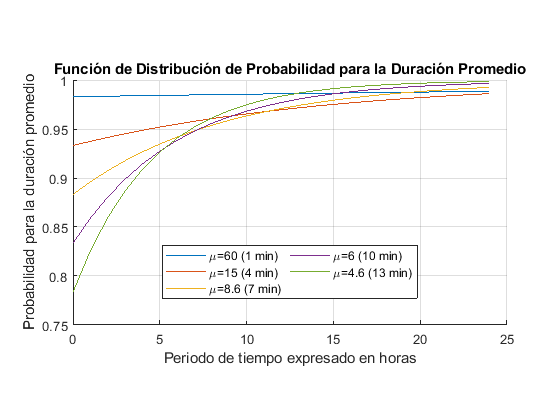

% Tiempo de servicio en minutos
ts=[1:3:15];
% Convertimos tiempo en horas y calculamos la tasa promedio de duración
mu=(ts/60).^-1;
% Definimos el intervalo de tiempo de observación en horas
t=[0:1:24];
% Configuramos la figura  
figure
hold on
% Graficamos para cada tasa de duración
for i=1:length(mu)
  % 
  p=1-exppdf(t,mu(i)); 
  % p=1-(mu(i)^-1)*exp(1).^(-mu(i)^-1*t); % equivalente
  plot(t,p)
  % Construimos data para la leyenda
  data{i}=['\mu='...
      num2str(mu(i),2)...
      ' ('...
      num2str(ts(i),2)...
      ' min)'];
end
% Configuramos la leyenda del grafico
legend(data,'Location','best','NumColumns',2)
% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
pbaspect([16 9 1])
% Configuramos los detalles del grafico
title('Función de Distribución de Probabilidad para la Duración Promedio')
xlabel('Periodo de tiempo expresado en horas')
ylabel('Probabilidad para la duración promedio')

## **E. Función de distribución de probabilidad para el promedio de arribo de llamadas**

Esta definida por una distribucion del tipo poisson

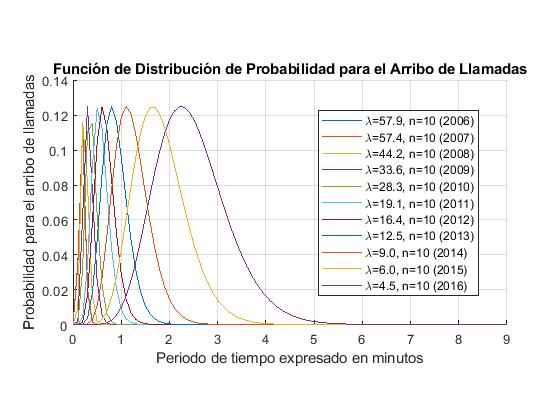

% Consideramos la tasa de duración de llamada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;
% Calculamos la tasa promedio de arribo de llamadas
lamda=mu.* T.TotalPeru./525600;
% Numero de arribos promedios en el tiempo
n=10;
% Definimos el intervalo de tiempo de observación en minutos
t=[0:.1:9];
% Configuramos la figura
figure
hold on
for i=1:length(lamda)
    % Extraemos el lambda correspodiente por cada año
    l=lamda(i);
    
    p=poisspdf(n,l*t);
    
    %p=(exp(1).^(-l*t)).*((l*t).^n)./factorial(n); % equivalente
    % Construimos data para la leyenda
    plot(t,p)
    % Construimos data para la leyenda
    data{i}=['\lambda='...
      num2str(lamda(i),'%2.1f')...
      ', n='...
      num2str(n,'%.0f')...
      ' ('...
      char(T.("Año")(i))...
      ')'];
end
% Configuramos la leyenda del grafico
legend(data,'Location','best','NumColumns',1)
% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
pbaspect([16 9 1])
% Configuramos los detalles del grafico
title(['Función de Distribución de Probabilidad para el Arribo de Llamadas'])
xlabel('Periodo de tiempo expresado en minutos')
ylabel('Probabilidad para el arribo de llamadas')

% Definimos el intervalo de tiempo de observación en minutos
t=[0:.1:10];
% 
N=[1:1:10];
%
l=lamda(11);
% Configuramos la figura
figure
hold on
for n=1:length(N)
    p=poisspdf(n,l*t);
    plot(t,p)        
    % Construimos data para la leyenda
    data{n}=['\lambda='...
      num2str(l,'%2.1f')...
      ', n='...
      num2str(n,'%.0f')...
      ' ('...
      char(T.("Año")(11))...
      ')'];
end
% Configuramos la leyenda del grafico
legend(data,'Location','best','NumColumns',1)

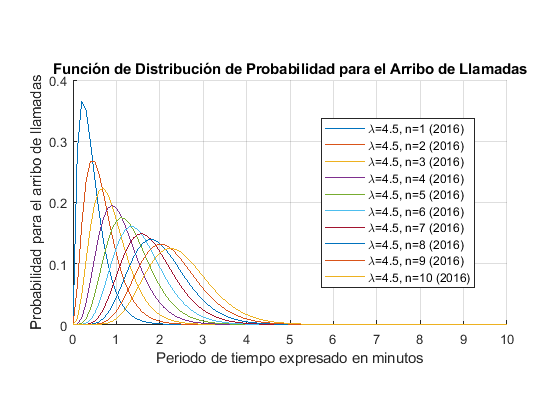

% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
pbaspect([16 9 1])
% Configuramos los detalles del grafico
title(['Función de Distribución de Probabilidad para el Arribo de Llamadas'])
xlabel('Periodo de tiempo expresado en minutos')
ylabel('Probabilidad para el arribo de llamadas')                   

## F. Trafico ofrecido en Erlangs

Esta definida por una distribucion del tipo exponecial

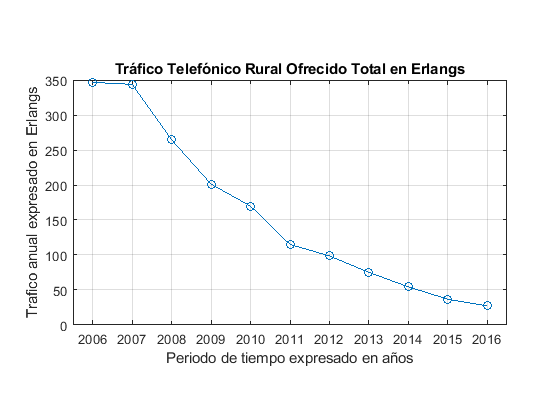

figure
A=T.TotalPeru./525600;
plot(T.("Año"),A,'-o')
grid on
pbaspect([16 9 1])
title('Tráfico Telefónico Rural Ofrecido Total en Erlangs')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico anual expresado en Erlangs')

## F. Volumen de trafico en minutos y Tráfico ofrecido en Erlangs

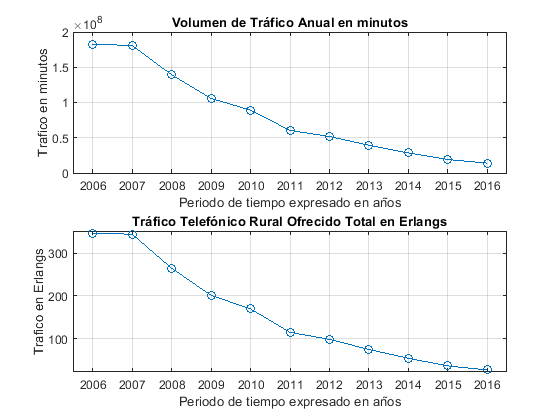

figure
subplot(2,1,1);
plot(T.("Año"),T.TotalPeru,'-o')
grid on
%pbaspect([16 9 1])
title('Volumen de Tráfico Anual en minutos')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico en minutos')

subplot(2,1,2); 
A=T.TotalPeru./525600;
plot(T.("Año"),A,'-o')
grid on
%pbaspect([16 9 1])
title('Tráfico Telefónico Rural Ofrecido Total en Erlangs')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico en Erlangs')

subplot(2,1,2)
xlim({'2006','2015'})
ylim([22 352])

subplot(2,1,2)
xlim({'2006','2016'})
ylim([22 352])